## MA431 - Project 2 - With Friction

clc; clear all; close all;

g = 9.81;
muk = 0.5375;
L = 2.015;
s_0 = 0.82;

syms t
eq = L == (1/2)*(s_0-((muk*L)/(1+muk)))*exp(sqrt((g/L)*(1+muk))*t)+(1/2)*(s_0-((muk*L)/(1+muk)))*exp((-sqrt((g/L)*(1+muk))*t))+((muk*L)/(1+muk))

$$eq = \frac{403}{200}=\frac{2843\,{\mathrm{e}}^{-\frac{3080380204927125\,t}{1125899906842624}}}{49200}+\frac{2843\,{\mathrm{e}}^{\frac{3080380204927125\,t}{1125899906842624}}}{49200}+\frac{17329}{24600}$$

t = vpa(solve(eq,t))

$$t = \left(\begin{array}{c} -1.1402151026701359015840828928031\\ 1.1402151026701359015840828928031 \end{array}\right)$$


t1 = 0;
idx = 1;
dt = 10^-3;
s = 0;
while s <= L
s = (1/2)*(s_0-((muk*L)/(1+muk)))*exp(sqrt((g/L)*(1+muk))*t1)+(1/2)*(s_0-((muk*L)/(1+muk)))*exp((-sqrt((g/L)*(1+muk))*t1))+((muk*L)/(1+muk));
t_plot(idx) = t1;
s_plot(idx) = s;
t1 = t1 + dt;
idx = idx + 1;
end

fig = figure;
plot(t_plot, s_plot, 'm','LineWidth',2)
ylim([min(s_plot) max(s_plot)])
%hold on
grid on
legend("Length of s", 'interpreter','latex')
title("Analytical Approach with Friction", 'interpreter','latex')
xlabel("Time [s]", 'interpreter','latex')
ylabel("Position [m]", 'interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
filename = "analytical_solution_with_friction_chain_problem.eps"

filename = "analytical_solution_with_friction_chain_problem.eps"

saveas(fig,filename, 'epsc')

## Numerical Approach, With Friction

simTime = 3; % s
t = 0; % Start time
idx = 1; % Index for logging
dt = 10^-4; % Time step

g = 9.81;

% I.C
s = s_0; % s(0) = 1 m (1 m of the chain is hanging of the table
sDot = 0; % s'(0) = 0 m/s

% Calculation
while s < L

    sDotDot = s * ((g/L) + (muk*g)/L) - (muk*g);

    % Save results for plotting
    timePlot(idx) = t;
    sPlot(idx) = s;
    sDotPlot(idx) = sDot;
    sDotDotPlot(idx) = sDotDot;

    % Time integrate y, yDot and update time, index variables
    s = s+sDot*dt;          % Position
    sDot = sDot+sDotDot*dt; % Velocity
    t = t+dt;               % Current time
    idx = idx+1;            % Index for logging
end

x = timePlot(sPlot<=L);
tot_time = x(end)

tot_time =           1.14029999999989


## Numerical Approach With Friction Plot

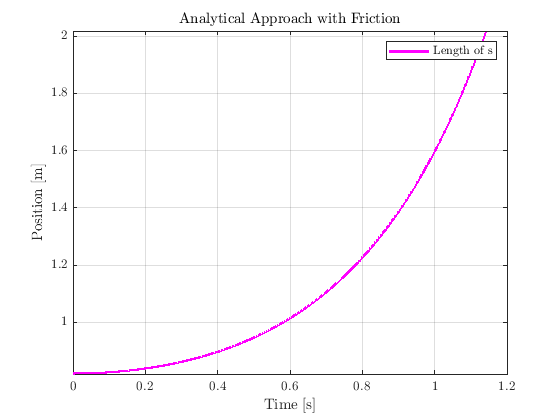

hold off

plot(timePlot(sPlot <= L), sPlot(sPlot <= L), 'b','LineWidth',2)
ylim([min(s_plot) max(s_plot)])
%hold on
%plot([0 3], [-2 -2])
grid on
legend("Numerical calculation", 'interpreter','latex')
title("Numerical Approach with Friction", 'interpreter','latex')
xlabel("Time [s]", 'interpreter','latex')
ylabel("Position [m]", 'interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
filename = "numerical_solution_with_friction_chain_problem.eps"

filename = "numerical_solution_with_friction_chain_problem.eps"

saveas(fig,filename, 'epsc')

## Analytical vs. Numerical approach with friction plot

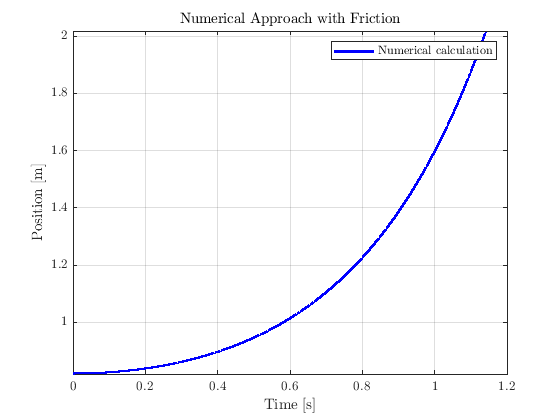

hold off

fig = figure;
plot(t_plot, s_plot, '--om','LineWidth',2, 'MarkerIndices', 1:30:length(s_plot))
hold on
plot(timePlot(sPlot <= L), sPlot(sPlot <= L), 'b','LineWidth',2)
ylim([min(s_plot) max(s_plot)])
grid on
legend("Length of s, analytical", "Length of s, numerical", 'interpreter','latex')
title("Analytical vs. Numerical Approach with Friction", 'interpreter','latex')
xlabel("Time [s]", 'interpreter','latex')
ylabel("Position [m]", 'interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
filename = "analytical_vs_numerical_solution_with_friction_chain_problem.eps"

filename = "analytical_vs_numerical_solution_with_friction_chain_problem.eps"

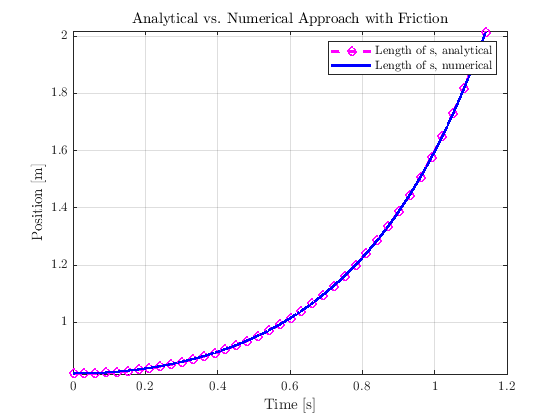

saveas(fig,filename, 'epsc')

## Figure for numerical with and without friction

simTime = 3; % s
t = 0; % Start time
idx = 1; % Index for logging
dt = 10^-4; % Time step

%L = 3; % Complete length of the chain
%s_0 = 1; % Length of the chain that is hanging of the table

% I.C
s = s_0; % s(0) = 1 m (1 m of the chain is hanging of the table
sDot = 0; % s'(0) = 0 m/s

% Calculation
while t < simTime

    sDotDot = (g/L) * s;

    % Save results for plotting
    timePlot_1(idx) = t;
    sPlot_2(idx) = s;

    % Time integrate y, yDot and update time, index variables
    s = s+sDot*dt;          % Position
    sDot = sDot+sDotDot*dt; % Velocity
    t = t+dt;               % Current time
    idx = idx+1;            % Index for logging
end

x = timePlot(sPlot<=L);
tot_time = x(end)

tot_time =           1.14029999999989


fig = figure;
plot(timePlot(sPlot_2 <= L), sPlot_2(sPlot_2 <= L), 'b','LineWidth',2)
hold on
plot(timePlot(sPlot <= L), sPlot(sPlot <= L), 'r','LineWidth',2)
grid
legend("Length of s, without friction", "Length of s, with friction", 'interpreter','latex')
title("Analytical vs. Numerical Approach with Friction", 'interpreter','latex')
xlabel("Time [s]", 'interpreter','latex')
ylabel("Position [m]", 'interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
filename = "with_friction_vs_without_friction_chain_problem.eps"

filename = "with_friction_vs_without_friction_chain_problem.eps"

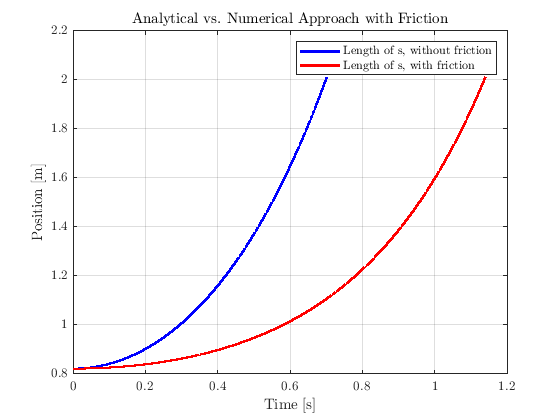

saveas(fig,filename, 'epsc')